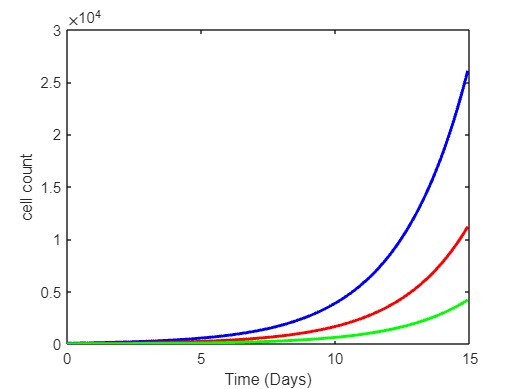


% Model parameters

% conc=0.55;
% EC50=190;
% data=importdata('Workspace.mat')
%%%%cell decrease due to cell cycle arrest and cell death
% fa=conc/(EC50 + conc);
fa=0;
% %%transition rates for cancerous condition
c1=0.85;
cs=1.59;
c2=3.85;

% % %%transition rates for normal condition
% c1=0.85/2;
% cs=1.59/2;
% c2=3.85/2;
x1 = 0.755;
x2 = 0.724;
x3 = 0.746;
calcium = [0.456100000000000
0.456071821000000
0.456043656000000
0.456015503000000
0.455850317000000
0.455685501000000
0.455521004000000
0.455356780000000
0.455025670000000
0.454695252000000
0.454365344000000
0.454035833000000
0.453706644000000
0.453292246000000
0.452878216000000
0.452464514000000
0.452051118000000
0.451638014000000
0.450888727000000
0.450140354000000
0.449392886000000
0.448646322000000
0.447900665000000
0.444353982000000
0.440828217000000
0.437323581000000
0.433840311000000
0.425036766000000
0.416378056000000
0.407867738000000
0.399509343000000
0.384157407000000
0.369396340000000
0.355236047000000
0.327678630000000
0.302653970000000
0.280204659000000
0.260234845000000
0.230860829000000
0.212473906000000
0.196869318000000
0.183565217000000
0.172153409000000
0.162264896000000
0.153668127000000
0.146142044000000
0.139509439000000
0.131344576000000
0.124393008000000
0.118404393000000
0.113197294000000
0.108636213000000
0.102707573000000
0.0977461000000000
0.0935514220000000
0.0899711310000000
0.0868888690000000
0.0842163990000000
0.0802129510000000
0.0770366920000000
0.0744927680000000
0.0724364940000000
0.0707589690000000
0.0693806250000000
0.0676663450000000
0.0663925830000000
0.0654457620000000
0.0647406100000000
0.0642140720000000
0.0638216610000000
0.0634049430000000
0.0631535670000000
0.0630142340000000
0.0629488800000000
0.0629317530000000
0.0629468830000000
0.0629849360000000
0.0630386350000000
0.0631028130000000
0.0631740060000000
0.0632499790000000
0.0634496180000000
0.0636598670000000
0.0638748790000000
0.0640921070000000
0.0647170120000000
0.0653534110000000
0.0660010010000000
0.0666603750000000
0.0681180730000000
0.0696399630000000
0.0712338620000000
0.0729094510000000
0.0758200920000000
0.0790423010000000
0.0826789410000000
0.0868919700000000
0.0919626180000000
0.0991927990000000
0.105647940000000
0.112039940000000
0.118609388000000
0.125388224000000
0.132652363000000
0.140476898000000
0.149121691000000
0.158826612000000
0.170138894000000
0.183131806000000
0.202060310000000
0.222560379000000
0.251571591000000
0.292046241000000
0.344436699000000
0.388162376000000
0.432461359000000
0.473556460000000
0.508637067000000
0.536181607000000
0.557669709000000
0.569217676000000
0.571649207000000
0.566082302000000
0.553761927000000
0.514530534000000
0.463214705000000
0.407652149000000
0.353268551000000
0.313147686000000
0.275932497000000
0.241828181000000
0.211198563000000
0.184556262000000
0.154404034000000
0.138069856000000
0.125703103000000
0.116525754000000
0.109788659000000
0.104877686000000
0.101324265000000
0.0982291420000000
0.0962551030000000
0.0950414310000000
0.0943513750000000
0.0940257460000000
0.0939736390000000
0.0941802330000000
0.0945562090000000
0.0950494120000000
0.0956277990000000
0.0968435370000000
0.0982081210000000
0.0996992850000000
0.101322190000000
0.103093252000000
0.106364794000000
0.110272944000000
0.115144742000000
0.119318517000000
0.123511068000000
0.128814312000000
0.133566742000000
0.138435503000000
0.144628177000000
0.150343713000000
0.157638218000000
0.164371662000000
0.172904094000000
0.181026126000000
0.191210519000000
0.201299371000000
0.213788982000000
0.229442472000000
0.245353802000000
0.264574228000000
0.287496547000000
0.314159175000000
0.353849328000000
0.385724714000000
0.417845890000000
0.448789278000000
0.477368477000000
0.513581888000000
0.541252746000000
0.559785695000000
0.569436844000000
0.570947005000000
0.561602435000000
0.541544259000000
0.513642077000000
0.480630729000000
0.444893322000000
0.390436334000000
0.338050814000000
0.289752027000000
0.246278391000000
0.208197870000000
0.169089063000000
0.146193944000000
0.129401730000000
0.117591305000000
0.109458553000000
0.104713971000000
0.101255030000000
0.0987604050000000
0.0969891490000000
0.0957578250000000
0.0948096000000000
0.0942646760000000
0.0940056590000000
0.0939527610000000
0.0940503690000000
0.0944022570000000
0.0949167410000000
0.0955398490000000
0.0962428660000000
0.0970096460000000
0.0984507140000000
0.100038177000000
0.101774276000000
0.103676621000000
0.108355214000000
0.112443968000000
0.116453310000000
0.119260793000000];
T = 15; % period of 15 days
dt = 1/15; % time interval                                                    day)

%deriv=[G,S,M,V];
[G,S,M,V] = cell_cycle(fa,c1,cs,c2,x1,x2,x3,calcium,T,dt);
% Plots that display the epidemic outbreak
tt = 0:dt:T-dt;
% Curve-+

plot(tt,G,'b',tt,S,'r',tt,M,'g','LineWidth',2); grid on;
xlabel('Time (Days)'); ylabel('cell count');

grid off

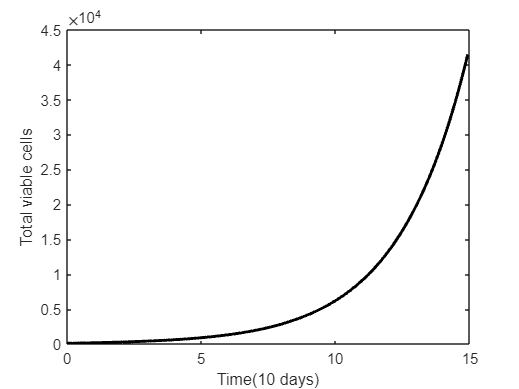

% legend('G','S','M');
plot(tt,V,'k','LineWidth',2);
xlabel('Time(10 days)'); ylabel('Total viable cells');

function [G,S,M,V] = cell_cycle(fa,c1,cs,c2,x1,x2,x3,calcium,T,dt)
    % if delta = 0 we assume a model without immunity loss
    G = zeros(1,T/dt);
    G(1) = 62.87;
    S = zeros(1,T/dt);
    S(1) = 26.93;
    M = zeros(1,T/dt);
    M(1)= 10.20;
    V = zeros(1,T/dt);
    V(1) = 100;
    for tt = 1:(T/dt)-1
        % Equations of the model
        dG = (2*c2*M(tt) - (c1*G(tt))) * dt;
        dS = (c1*G(tt) - (cs*(1-fa)*S(tt))) * dt;
        dM = ((cs*(1-fa)*S(tt)) - (c2*M(tt))) * dt;
        G(tt+1) = G(tt) + dG + (x1.*calcium(tt));
        S(tt+1) = S(tt) + dS + (x2.*calcium(tt));
        M(tt+1) = M(tt) + dM + (x3.*calcium(tt));
        V(tt+1) = G(tt+1)+ S(tt+1) + M(tt+1);
        
        
    end
end

